Modelo de Regresión Lineal por mínimos cuadrados

x = [1 2 3 4 5]

x =      1     2     3     4     5


y = [2 3 4 5 6]

y =      2     3     4     5     6


n = length(x);
TablaMC = [x' y' (x.^2)' (x.*y)']

TablaMC =      1     2     1     2
     2     3     4     6
     3     4     9    12
     4     5    16    20
     5     6    25    30


E_x = sum(TablaMC(:,1));
E_y = sum(TablaMC(:,2));
E_x2 = sum(TablaMC(:,3));
E_xy = sum(TablaMC(:,4));

a = (n*E_xy - E_x*E_y)/(n*E_x2- E_x.^2)

a = 1

b=(E_y -a*E_x)/n

b = 1

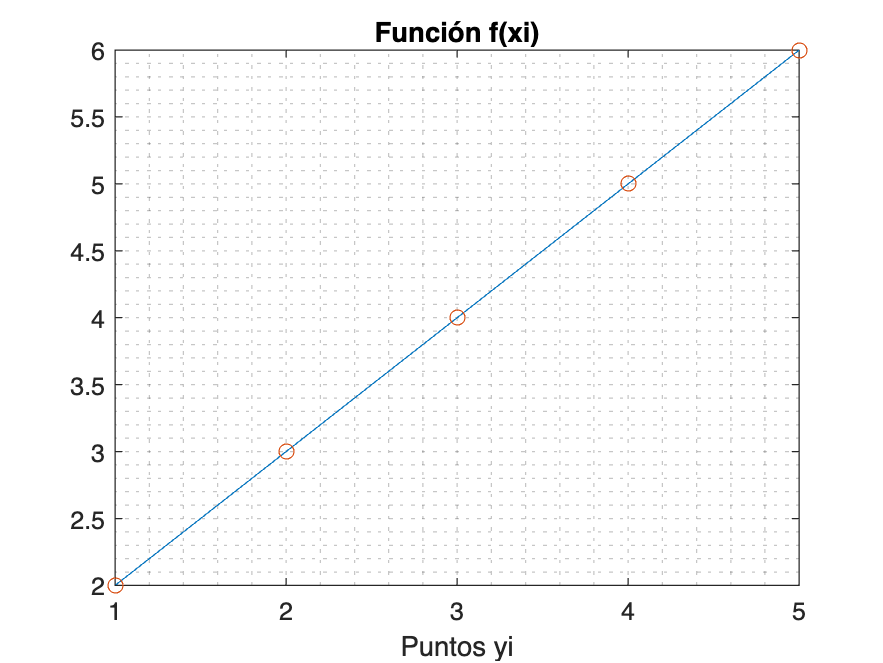

f = @(x) a*x+b;
plot(x,f(x))
hold on
scatter(x,y); %graficar con dispersión
grid minor;
title('Función f(xi)'); xlabel('Puntos xi');xlabel('Puntos yi')
hold off